clear;
clear all;
clc;

## Entrega 5 - PMR3523 Controle Moderno

## Teste de Controlabilidade e Observabilidade

#### Ângelo Bianco Yanagita - 6649978 

#### Diôgo Cavalcante Rodrigues Lopes - 11180872

As equações utilizadas são:


$$(1) \; \dot{x}_G=u\cdot cos(\psi)-v\cdot sin(\psi)\\
(2) \; \dot{y}_G=u\cdot sin(\psi)+v\cdot cos(\psi)\\
(3) \; \dot{\psi}=r \\
(4) \; (M+M_{11})\dot{u}-(M+M_{22})v\cdot r -(M\cdot x_G + M_{26})r^2 = F_x \\
(5) \; (M+M_{22})\dot{v}+(M\cdot x_G+M_{26})\dot{r} +(M + M_{11})u\cdot r = F_y \\
(6) \; (I_Z+M_{66})\dot{r}+(M\cdot x_G+M_{26})(\dot{v}+u\cdot r) + (M_{22} - M_{11})u\cdot v = M_z
$$


Sendo as variáveis:

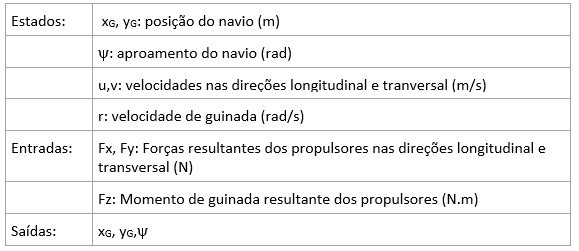


$$\begin{array}{l}
x={\left\lbrack \begin{array}{cccccc}
x_g  & y_g  & \psi \; & u & v & r
\end{array}\right\rbrack }^T \\
u={\left\lbrack \begin{array}{ccc}
F_x  & F_y  & F_z 
\end{array}\right\rbrack }^T \\
y={\left\lbrack \begin{array}{ccc}
x_g  & y_g  & \psi \;
\end{array}\right\rbrack }^T 
\end{array}$$


Colocando os termos na forma matricial do espaço de estados:


$$\begin{array}{l}\delta \dot{x} =A\delta x\left(t\right)+B\delta u\left(t\right)\\\;\delta 
y=C\delta x\left(t\right)+D\delta u\left(t\right)\;\end{array}$$



$$A_{6x6}=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
 
$$B_{6x3}=10 ^{-10}\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1269  & 0 & 0\\
0 & 734 & -1,345\\
0 & -1,345 & 2,323
\end{array}\right\rbrack$$
 
$$C_{3x6}=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack$$
  
$$D=0$$


## Matriz de Transferência

$G\left(s\right)=\frac{\left\lbrack \begin{array}{ccc}
\left(1\ldotp 2690E-07\right)s^4  & 0 & 0\\
0 & \left(7\ldotp 3395E-08\right)s^4  & \left(1\ldotp 3453E-10\right)s^4 \\
0 & \left(1\ldotp 3453E-10\right)s^4  & \left(2\ldotp 3225E-10\right)s^4 
\end{array}\right\rbrack }{s^6 }$=$\left\lbrack \begin{array}{ccc}
\frac{\left(1\ldotp 2690E-07\right)}{s^2 } & 0 & 0\\
0 & \frac{\left(7\ldotp 3395E-08\right)}{s^2 } & \frac{\left(1\ldotp 3453E-10\right)}{s^2 }\\
0 & \frac{\left(1\ldotp 3453E-10\right)}{s^2 } & \frac{\left(2\ldotp 3225E-10\right)}{s^2 }
\end{array}\right\rbrack$

Como pode-se observar pela matriz de transferência acima, ocorre cancelamento dos quatro zeros de multiplicidade 4 no ponto zero com os quatro polos de multiplicidade 4 no ponto zero.

## Verificação da controlabilidade e da observabilidade:

#### A) Controlabilidade


$$C=\left\lbrack B\;\mathrm{AB}\;A^2 B\;\ldotp \ldotp \ldotp A^{n-1} B\right\rbrack$$


Então:


$$C=$$

$$1E-06\left\lbrack \begin{array}{cccccccccc}
0 & 0 & 0 & 0\ldotp 1269 & 0 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 0 & 0 & 0 & 0\ldotp 0734 & -0001 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 0 & 0 & 0 & -0\ldotp 0001 & 0\ldotp 0002 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0\ldotp 1269 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & 0\ldotp 0734 & -0\ldotp 0001 & 0 & 0 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & -0\ldotp 0001 & 0\ldotp 0002 & 0 & 0 & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0
\end{array}\right\rbrack$$


E o $\mathrm{Posto}\left(C\right)=6$, logo o sistema é controlável, pois o número do posto é igual a ordem do sistema.

#### B) Observabilidade


$$O=\left\lbrack \begin{array}{c}
C\\
\mathrm{CA}\\
{\mathrm{CA}}^2 \\
\ldotp \\
\ldotp \\
{\mathrm{CA}}^{n-1} 
\end{array}\right\rbrack \;$$


Portanto:


$$O=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Resutando em $\mathrm{Posto}\left(O\right)=6$, sendo assim, o sistema é observável, pois o número do $\mathrm{Posto}\left(O\right)$ é igual a ordem do sistema